Load the dataset 

load ionosphere.mat;
str = convertCharsToStrings(Y);
label = str == 'g';
tabulate(Y)

  Value    Count   Percent
      g      225     64.10%
      b      126     35.90%


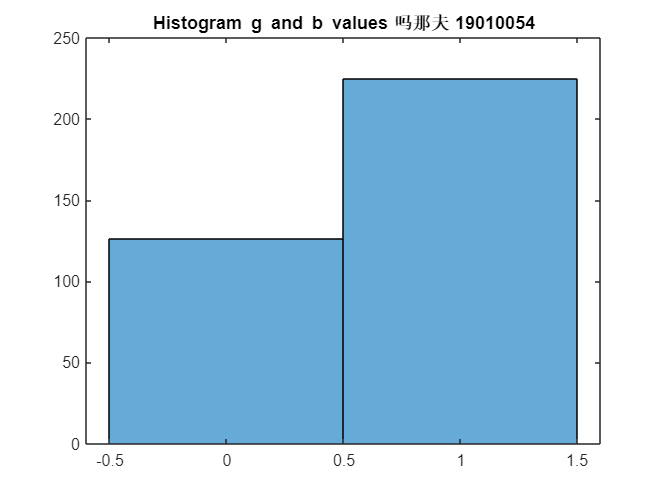

histogram(label)
title('Histogram g and b values_ 吗那夫_ 19010054')

**Split the data set**

m =length(label);
P = 0.7;
idx = randperm(m);
num_train = round(P*m);
X_Training = X(idx(1:num_train),:);
Y_Training = Y(idx(1:num_train),:);
X_Testing = X(idx(1:(num_train+1):end),:);
Y_Testing = Y(idx(1:(num_train+1):end),:);

## Linear Regression Model 

%fitting the model using linear regression
lrm = fitglm(X_Training, Y_Training)

Error using double
Conversion to double from cell is not possible.

Error in internal.stats.numericPrototype (line 48)
    prototype = double(prototype);

Error in classreg.regr.FitObject/assignData (

normalEQT = (inv(X_Training'*X_Training))*(X_Training'*Y_Training);
fprintf('%f',normalEQT);
predict = X_Testing*normalEQT;
fprintf('%f', predict);